# Ejercicio 6

## a) 

Construir algoritmo:

function R = mychol(A)
    
    R = triu(A);
    m = size(A, 1); 
    
    for k = 1:m
        for j = k+1:m
            R(j, j:m) = R(j, j:m) - (R(k, j:m) * R(k, j) / R(k, k));
        end
        R(k, k:m) = R(k, k:m) / sqrt(R(k, k));
    end
end


## b)

Note que si definimos $

A= P^T P =P^T (P^T)^T = (P^T P)^T = A^T$ siendo $P \in R^{mxm}$, entonces se tiene una matriz simétrica.

Ademas note que $x^T A x = x^T (P^T P) x = (P x)^T (P x) = \| P x \|^2$ y como $ 0 \leq  \| P x \|^2 $ entonces cumple con la propiedad definida positiva.

% Definir matriz A
m = 20;
P = rand(m,m); % Crea matriz cuadrada aleatoria 20x20
A = P' * P;
% Obtener factorización de Cholesky
R = mychol(A);

Calcular error a partir de norma dos:

err1 = norm(A - R' * R);
disp(err1)

   7.9034e-15



Factorizacion con función de MATLAB:

R_m = chol(A); 

Calcular error a partir de norma dos para la función de MATLAB:

err2 = norm(A - R_m' * R_m);
disp(err2)

   6.5779e-15



Nótese que que el resultado de la factorización a partir del algoritmo construido presenta un error` considerablemente bueno y aceptable. No obstante, la factorización que presenta MATLAB tiene un error de más pequeño (con un cero más de exactitud en ocaciones), siendo un algoritmo más preciso.`

## c)

Definir la matriz A como una de Hilbert:

m = 20;
A = hilb(m);

### Repitiendo el inciso anterior

Utilizando el algoritmo construido:

% Obtener factorización de Cholesky
R_h = mychol(A)

R_h =    1.0000 + 0.0000i   0.5000 + 0.0000i   0.3333 + 0.0000i   0.2500 + 0.0000i   0.2000 + 0.0000i   0.1667 + 0.0000i   0.1429 + 0.0000i   0.1250 + 0.0000i   0.1111 + 0.0000i   0.1000 + 0.0000i   0.0909 + 0.0000i   0.0833 + 0.0000i   0.0769 + 0.0000i   0.0714 + 0.0000i   0.0667 + 0.0000i   0.0625 + 0.0000i   0.0588 + 0.0000i   0.0556 + 0.0000i   0.0526 + 0.0000i   0.0500 + 0.0000i
   0.0000 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2598 + 0.0000i   0.2309 + 0.0000i   0.2062 + 0.0000i   0.1856 + 0.0000i   0.1684 + 0.0000i   0.1540 + 0.0000i   0.1417 + 0.0000i   0.1312 + 0.0000i   0.1221 + 0.0000i   0.1142 + 0.0000i   0.1072 + 0.0000i   0.1010 + 0.0000i   0.0955 + 0.0000i   0.0906 + 0.0000i   0.0861 + 0.0000i   0.0820 + 0.0000i   0.0784 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0745 + 0.0000i   0.1118 + 0.0000i   0.1278 + 0.0000i   0.1331 + 0.0000i   0.1331 + 0.0000i   0.1304 + 0.0000i   0.1265 + 0.0000i   0.1220 + 0.0000i   0.1173 + 0.0000i   0.1126 + 0.0000i   0

Note que la matriz triangular superior que genera contiene números cumplejos, esto se da porque la matriz de Hilbert no cumple con la condición de definida positiva.

% Calcular error a partir de norma dos:
err_h = norm(A - R_h' * R_h);
disp(err_h)

   3.0393e-09



Note que el error a pesar de ser bajo, si es considerablemente más grande que los que han generado las matrices aleatorias. Esto se puede justificar por el hecho que el algoritmo no está hecho para este tipo de matríz, pues como se mencionó la de Hilbert no es definida positivia.

Con la función de MATLAB:

%R_h2 = chol(A); 

Note que para la función de factorización nativa en MATLAB no se puede ni obtener un resultado ya que la función lo impiede si la matriz no cumple con definida positiva, como en este caso la de Hilbert.

### Resolver sistema Ax = b

% Definición se solución exacta
x = ones(20, 1);

% Definir el valor de b
b = A * x;

Dado que $A$ se puede factorizar como $A = R^T R$, entonces para resolver el sistema se tiene $R^TRx = b$, tomando $y = Rx$ se sigue que la solución del sistema es:

y = R_h' \ b;
x_aprox = R_h \ y;

Obtener el error de la solución del sistema:

error_sol = norm(x - x_aprox)

error_sol = 9.8641e+04

#### ¿Es el error en la solución numérica del sistema el esperado?

La respuesta es si, pues como sabemos primero que todo la matriz de Hilbert está extremadamente mal condicionada, además que la factorización de Cholesky es para matrices simétricas y definidas positivas, donde Hilbert no cumple la ultima condición, como se ha mencionado a lo largo del ejercicio. Por lo tanto, esperaba un error bastante alto para solución del sistema con esta matriz y método de factorización.

# Ejercicio 7

## a)

Para ver que $y(t) = t + e^{-t} - 1$ satisface la ecuación diferencial $y\prime  = t - y$, note que al derivar $y(t)$ se tiene:


$$y'=y'(t) = 1-e^{-t}$$


Ahora sustituyendo la función $y(t)$ al lado izquierdo de la ecuación diferencial se tiene:


$$t-y = t-(t+e^{-t}-1)=1-e^{-t}$$


Note que al realizar las sustituciones se llega al mismo resultado ambos lados de la igualdad, por lo tanto, se concluye que $y(t) = t + e^{-t} - 1$ es una solucióin de la ecuación diferencial dada.

## b)

Según el enunciado se sigue que $y_k'= f(t_k, y_k)  \Rightarrow y_k' = t_k - y_k$, la interación explícita de Euler está dada por:


$$y_{k+1} = y_k + h \cdot f(t_k, y_k) \quad (k \geq 0), \quad y_0 =y(t_0)= y(0),
$$


Dado que nos encontramos en el intervalo $(0,10)$ y son $n$ particiones entonces:


$$h =\frac{10}{n}$$


Ahora sustituyendo expresiones en la ecuación de la iteración:

$\Rightarrow \quad y_{k+1}=y_k+\frac{10}{n}(t_k-y_k)$   para $k \in \{0,1, \cdots, n \}$

De esta manera se obtiene la iteración que brinda el método de Euler para la ecuación diferencial dada.

## c)

Se tiene que la interación para $y_{k+1}$ del método del trapecio es:


$$y_{k+1} = y_k + \frac{1}{2} h \left[ f(t_k, y_k) + f(t_{k+1}, y_{k+1}) \right] \quad (k \in \{0, \cdots,n \}), \quad y_0 = y(t_0),
$$


Como en incisos anteriores se tiene que$f(t_k,y_k) = t_k - y_k$ para $k \in \{0, \cdots,n \}$ y que $h=\frac{10}{n}$, entonces sustituyendo:


$$y_{k+1} = y_k + \frac{h}{2n}  \left[ (t_k -y_k) + (t_{k+1}- y_{k+1}) \right] $$


Así tenemos que la interación en forma explícita del método del trapecio para la ecuación diferencial dada.

## d)

Definición de parámetros globales para las funciones:

% Parámetros iniciales
x0 = 0;
y0 = 0; % Valor inicial de y
x_end = 10;
n = 20; % número de pasos
h = (x_end - x0) / n;

% Definir la función f(x, y) = t - y
f = @(t, y) t - y;



#### Solución exacta:


% Vector de puntos t para la solución exacta usando el tamaño de paso h
t = x0:h:x_end; % Esto genera un vector con incrementos de h desde x0 hasta x_end

y_exacta = t + exp(-t) - 1; 

% Gráfico
figure;
plot(t, y_exacta, 'b-o', 'LineWidth', 1.5); hold on; % Solución exacta
xlabel('t');
ylabel('y');
grid on;

#### Función para aproximar por métod de Euler:

function [x_val, y_val] = euler(f, x0, y0, h, n)
    % Argumentos:
    %   f : La función que define la derivada dy/dx = f(x, y).
    %   x0: El valor inicial de x.
    %   y0: El valor inicial de y.
    %   h : El tamaño del paso.
    %   n : El número de nodos o integraciones.

    % Inicialización de los valores de x y y
    x_val = zeros(1, n+1);
    y_val = zeros(1, n+1);
    x_val(1) = x0;
    y_val(1) = y0;

    % Loop para el método de Euler
    for i = 1:n
        x = x_val(i);
        y = y_val(i);
        
        y_new = y + h * f(x, y);
        x_new = x + h;
        
        x_val(i+1) = x_new;
        y_val(i+1) = y_new;
    end
end



% Llamar a la función de método de Euler
[x_eu, y_eu] = euler(f, x0, y0, h, n);

% Graficar
plot(x_eu, y_eu, '-', 'Color', 'y', 'MarkerFaceColor', 'y')
xlabel('x')
ylabel('y')
title('Aproximaciones con Método de Euler y Método del Trapecio');
grid on

#### Función para aproximar por método del Trapecio:

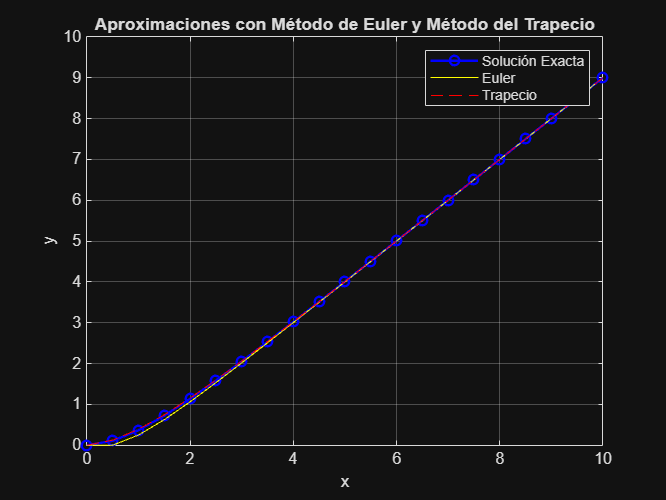

function [x_val, y_val] = trapecio(f, x0, y0, h, n)
    % Método del Trapecio para resolver una EDO de primer orden.
    %
    % Argumentos:
    %   f : La función que define la derivada dy/dx = f(x, y).
    %   x0: El valor inicial de x.
    %   y0: El valor inicial de y.
    %   h : El tamaño del paso.
    %   n : El número de nodos o integraciones.
    %
    % Returns:
    %   x_val: Lista de valores de x.
    %   y_val: Lista de valores de y.

    % Inicialización de los valores de x y y
    x_val = zeros(1, n+1);
    y_val = zeros(1, n+1);
    x_val(1) = x0;
    y_val(1) = y0;

    % Loop para el método del Trapecio
    for i = 1:n
        x = x_val(i);
        y = y_val(i);
        
        % Predicción con Euler
        y_predict = y + h * f(x, y);
        x_new = x + h;
        
        % Corrección usando el método del Trapecio
        y_new = y + (h / 2) * (f(x, y) + f(x_new, y_predict));
        
        % Almacenar los nuevos valores
        x_val(i+1) = x_new;
        y_val(i+1) = y_new;
    end
end

% Llamar a la función de método del Trapecio
[x_tr, y_tr] = trapecio(f, x0, y0, h, n);

% Graficar el resultado
plot(x_tr, y_tr, '--', 'Color', 'r', 'MarkerFaceColor', 'r')
xlabel('x')
ylabel('y')
title('Aproximaciones con Método de Euler y Método del Trapecio');
legend('Solución Exacta','Euler','Trapecio');
grid on

## e)

Definición de variables:

x0 = 0;
y0 = 1;
x_end = 10;

% Valores de n 
n_val = [10, 20, 40, 80, 160, 300, 400];

% Vectores para guardar las norma infinita
error_eu_inf = zeros(length(n_values), 1);
error_tr_inf = zeros(length(n_values), 1);

% Función que representa la derivada 
f = @(t, y) t - y;

% Solución exacta de la ecua
y_exact = @(t) t - 1 + 2 * exp(-t);


Cálculo de normas:

% for para recorre cada valor de n
for j = 1:length(n_val)
    n = n_val(j);
    h = (x_end - x0) / n;
    t_val = linspace(x0, x_end, n+1);  % Valores de t

    % Euler
    [x_eu, y_eu] = euler(f, x0, y0, h, n);
    error_eu = abs(y_exact(t_val) - y_eu);
    error_eu_inf(j) = max(error_eu);  

    % Trapecio
    [x_tr, y_tr] = trapecio(f, x0, y0, h, n);
    error_tr = abs(y_exact(t_val) - y_tr);
    error_tr_inf(j) = max(error_tr);  % Norma infinita del error
end

% Valores de h para la gráfica
h_val = (x_end - x0) ./ n_val;


Graficar errores en función de n para la norma infinita:

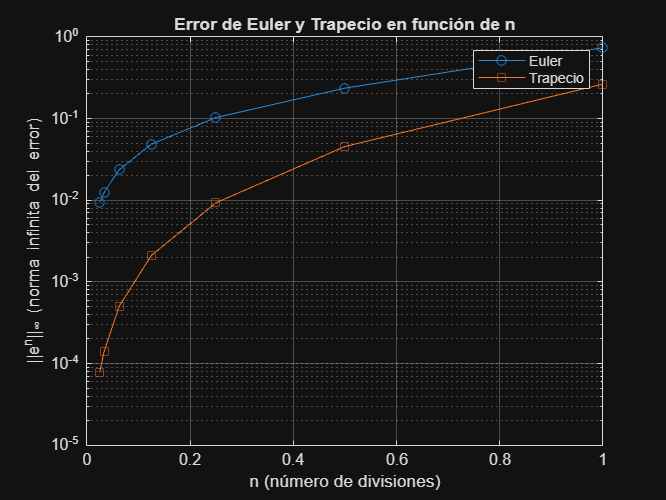

figure;
semilogy(h_val, error_eu_inf, 'o-', 'DisplayName', 'Euler');
hold on;
semilogy(h_val, error_tr_inf, 's-', 'DisplayName', 'Trapecio');
xlabel('n (número de divisiones)');
ylabel('||e^n||_\infty (norma infinita del error)');
title('Error de Euler y Trapecio en función de n');
legend;
grid on;

Para la gráfica se tomaron hasta valores de $n=1000$ donde se ve que el método de Trapecio que llega a $10^{-4}$, superando al método de Eurler, donde este  llega a$10^{-2}$. Mostrando cual método tiene mejor rendimiento para la aproximación de la solución de la ecuación diferencial.a

# Ejercicio 8

## a)

Considera las variables $\( z = \frac{dx}{dt} \)$ y $\( w = \frac{dy}{dt} \)$, entonces se sigue:


$$z' = \frac{d^2 x}{dt^2} = x + 2w - uc \cdot \frac{x + u}{((x+u)^2 + y^2)^{3/2}} - u \cdot \frac{x - uc}{((x-uc)^2 + y^2)^{3/2}}$$



$$w' = \frac{d^2 y}{dt^2} = y - 2z - uc \cdot \frac{y}{((x+u)^2 + y^2)^{3/2}} - u \cdot \frac{y}{((x-uc)^2 + y^2)^{3/2}}$$


Por lo tanto, tiene el sistema de ecuaciones:

                                             
$$\[
\begin{cases}
x' = z, \\
y' = w, \\
z' = x + 2w - uc \cdot \frac{x + u}{((x+u)^2 + y^2)^{3/2}} - u \cdot \frac{x - uc}{((x-uc)^2 + y^2)^{3/2}}, \\
w' = y - 2z - uc \cdot \frac{y}{((x+u)^2 + y^2)^{3/2}} - u \cdot \frac{y}{((x-uc)^2 + y^2)^{3/2}}.
\end{cases}
\]$$


El sistema en forma matricial es:

                                             
$$\[
\mathbf{u}' = 
\pmatrix{
x' \cr
y' \cr
z' \cr
w'
} 
= 
\pmatrix{
z \cr
w \cr
x + 2w - uc \cdot \frac{x + u}{((x+u)^2 + y^2)^{3/2}} - u \cdot \frac{x - uc}{((x-uc)^2 + y^2)^{3/2}} \cr
y - 2z - uc \cdot \frac{y}{((x+u)^2 + y^2)^{3/2}} - u \cdot \frac{y}{((x-uc)^2 + y^2)^{3/2}}
}
\]
$$


Para las condiciones iniciales se tiene como el vector:

                                             
$$\[
\mathbf{u}(0) = 
\pmatrix{
x(0) \cr
y(0) \cr
z(0) \cr
w(0)
} 
= 
\pmatrix{
0.994 \cr
0 \cr
0 \cr
-2.001585106
}
\]
$$


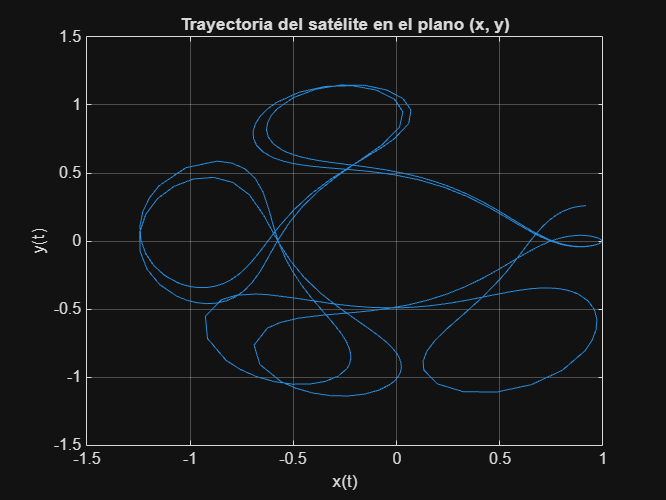

% Parámetros
u_const = 0.012277471; % Le puse const porque se me confundía con con el vector u e la matriz del sistema
uc_const = 1 - u_const;

% Condiciones iniciales
u0 = [0.994; 0; 0; -2.001585106];


% Definir el sistema de ecuaciones diferenciales como una función anónima
f = @(t, u) [
    u(3);  % dx/dt = z
    u(4);  % dy/dt = w
    u(1) + 2*u(4) - uc_const * (u(1) + u_const) / ((u(1) + u_const).^2 + u(2).^2).^(3/2) - u_const * (u(1) - uc_const) / ((u(1) - uc_const).^2 + u(2).^2).^(3/2);  % dz/dt
    u(2) - 2*u(3) - uc_const * u(2) / ((u(1) + u_const).^2 + u(2).^2).^(3/2) - u_const * u(2) / ((u(1) - uc_const).^2 + u(2).^2).^(3/2)  % dw/dt
];

% Resolver el sistema usando ode113
[t, u] = ode113(f, [0, 40], u0);

% Extraer soluciones x(t) y y(t)
x = u(:, 1);
y = u(:, 2);

% Graficar la curva paramétrica (x(t), y(t))
figure;
plot(x, y);
xlabel('x(t)');
ylabel('y(t)');
title('Trayectoria del satélite en el plano (x, y)');
grid on;

Se puede observar como se realizan movimientos circulares en 2 dimensiones , que sería la trayectoria que presentó el satélite.

## c)

Definir vector:

options = odeset('RelTol', 1e-10, 'Stats', 'on', 'AbsTol', 1e-10);

Ejecutar el comando:

[t2,u2] = ode113(f,[0 40],u0,options)

1914 successful steps
27 failed attempts
3856 function evaluations


t2 =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


u2 =     0.9940         0         0   -2.0016
    0.9940   -0.0000   -0.0000   -2.0016
    0.9940   -0.0000   -0.0000   -2.0016
    0.9940   -0.0000   -0.0000   -2.0016
    0.9940   -0.0000   -0.0000   -2.0016
    0.9940   -0.0000   -0.0001   -2.0016
    0.9940   -0.0000   -0.0002   -2.0016
    0.9940   -0.0000   -0.0003   -2.0016
    0.9940   -0.0000   -0.0006   -2.0016
    0.9940   -0.0000   -0.0013   -2.0016


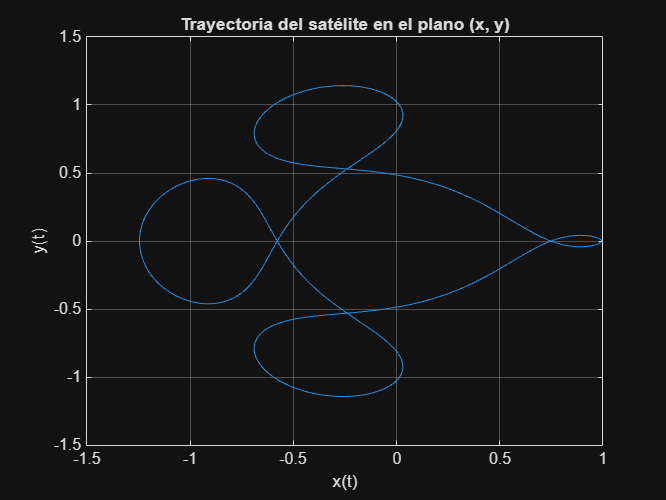

% Extraer soluciones x(t) y y(t)
x2 = u2(:, 1);
y2 = u2(:, 2);


% Graficar la curva paramétrica (x(t), y(t))
figure;
plot(x2, y2);
xlabel('x(t)');
ylabel('y(t)');
title('Trayectoria del satélite en el plano (x, y)');
grid on;

Muestra una muy alta aproximación, ya que no se ve desfasada en ningun punto la gráfica

# Ejercicio 9